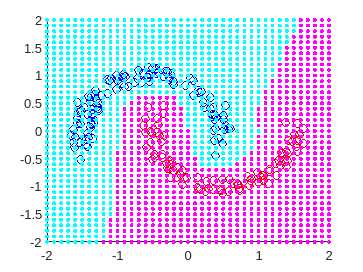

load D2z.txt

D2z0 = D2z(D2z(:,3)==1,1:2);
D2z1 = D2z(D2z(:,3)==0,1:2);
figure
scatter(D2z0(:,1),D2z0(:,2), 'b')
hold on
scatter(D2z1(:,1),D2z1(:,2), 'r')

[x1, x2] = meshgrid(-2:0.1:2, -2:0.1:2);
x1 = reshape(x1, [], 1);
x2 = reshape(x2, [], 1);
X = [x1 x2];

mdl = fitcknn(D2z(:,1:2), D2z(:,3), Distance='euclidean', NumNeighbors=1);
y = predict(mdl, X);

X0 = X(y == 0, :);
X1 = X(y ~= 0, :);
scatter(X0(:,1), X0(:,2), 'm.')
scatter(X1(:,1), X1(:,2), 'c.')

exportgraphics(gcf, 'hw3_1.pdf', ContentType='vector')